# **EtherCAT Emulator with TwinCAT**

EtherCAT is a fast Ethernet based real-time communication protocol that allows the EtherCAT main device (usually a controller in a plant) to exchange data with multiple subordinate devices (sensors and actuators on the field level of a plant). The protocol supports cyclic data transmission through process data objects (PDO), and enables parameter read/write operations via service data objects (SDO)*. * 

This example demonstrates the communication between TwinCAT, as the EtherCAT main device, and a Speedgoat real-time target machine simulating several EtherCAT subordinate devices such as a motor controller and a bus coupler hosting analog and digital input and output modules.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least one unused Ethernet interface

- "Runtime License File" that includes an EtherCAT Emulator license for 6 nodes. Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

- Computer that runs TwinCAT from Beckhoff

### Ethernet Configuration of the Emulator

Open the **Speedgoat Ethernet Configuration Tool** and select **EtherCAT** as the interface you want to use with the emulator. Assign the seat number of the interface in the list (starting at 1 for the interface after the Host Link) to the **Interface ID** parameter of all EtherCAT Emulator blocks in the model.

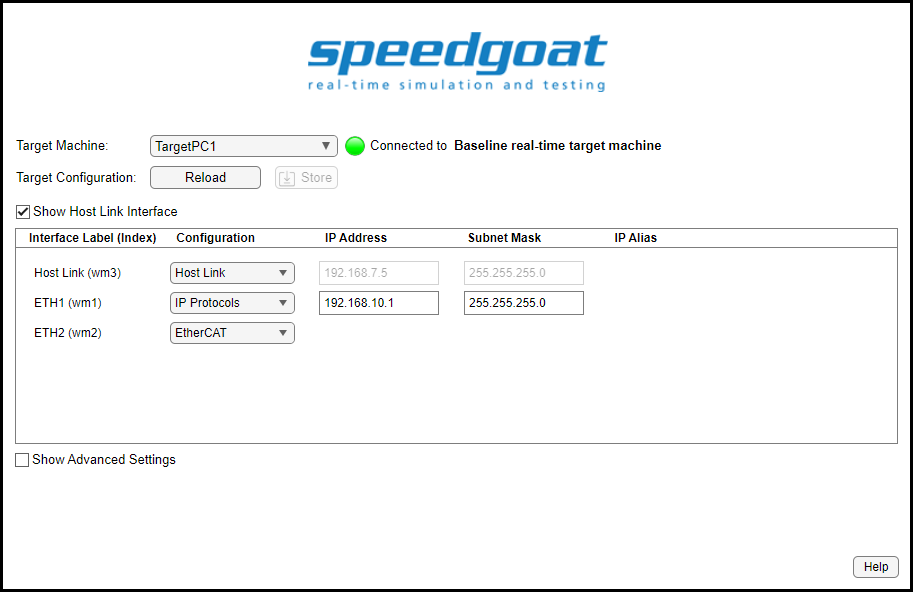

### Ethernet Configuration of the TwinCAT Computer

Open the **Network and Internet** settings, select the Ethernet interface you want to use for EtherCAT communication, edit the IP settings and select **Automatic (DHCP)**.

### TwinCAT Installation and Configuration

TwinCAT must be installed on a Windows-based computer in order to turn it into a programmable logic controller (PLC) with EtherCAT communication capabilities and the ability to run a simple PLC application.

Download the following tools from the Beckhoff website (registration required) and install both on the computer that should act as the controller.

- TwinCAT 3 eXtended Automation Engineering (XAE)

- TwinCAT 3 Controller Toolbox TF4100

The TwinCAT project included in this example was created with TwinCAT 3.1 Build 4024.67 and Controller Toolbox Version 2.2.4. on a Windows 11 computer.

Copy the C5-E-1-21.xml file to C:\TwinCAT\3.1\Config\Io\EtherCAT. This introduces the EtherCAT subordinate information file (ESI) of the Nanotech motor controller to TwinCAT. The ESI files of the other devices do not need to be installed as they all are Beckhoff devices and are already known to TwinCAT.

Open the zipped project (EtherCAT_Emulator_TwinCAT.tnzip) in TwinCAT using the **Open Solution from Archive** option.

In the left-hand tree, navigate to **I/O** and click **Device 1 (EtherCAT)**. On the right, open the **Adapter** tab and click **Search**. Select the interface you want to use for EtherCAT communication. If not listed, click **Compatible Devices** and install the driver for that interface.

To allow TwinCAT to run a PLC application on the computer, you must isolate one CPU core and assign all tasks to that core. Find the table below in **SYSTEM** > **Real-Time** > **Settings**. Click the **Read from Target** button to read the CPU configuration, change one core to **Isolated** and store the configuration using the **Set on Target** button.

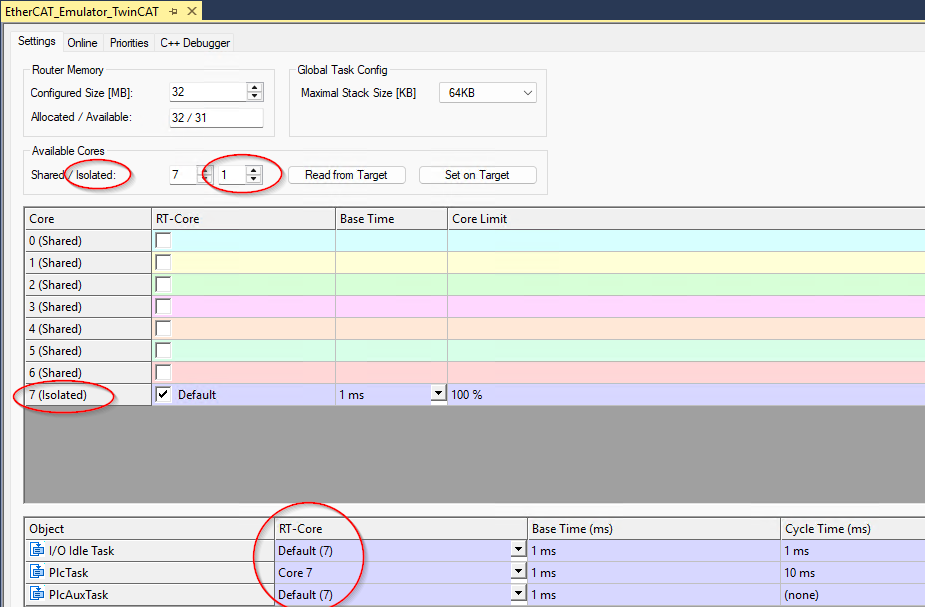

If changes to the core configuration are not permitted on your computer, you can still get the EtherCAT communication running, but you must forgo the PLC application. Click **TwinCAT** > **Restart TwinCAT (Config Mode)** and confirm the message boxes that read **Load I/O Devices** and **Activate Free Run**. You can also activate free-run from the **Toggle Free Run State** menu button. To monitor or change EtherCAT variables, click a variable in the I/O configuration section. In the **Online** tab, you can watch and force the variable's value.

If a real Beckhoff PLC is available, you can choose this device as the target system. This avoids having to isolate cores, and will also ensure that the PLC application runs without issues.

### Target Machine Wiring

Use a CAT5 cable or newer to connect the emulator's Ethernet interface with the Ethernet adapter of the TwinCAT-featured computer.

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_EtherCAT_Emulator_TwinCAT';
open_system(modelName);

### Model Description

The EtherCAT Emulator Setup block configures the EtherCAT protocol stack to emulate the EtherCAT devices described in the selected EXI (extended EtherCAT network information) file. The Send, Receive and Object blocks only exchange data with the internal memory of the protocol stack, but do not trigger any frames on the network. 

Change the **Interface ID** parameter according to the Ethernet adapter you want to use to connect to the EtherCAT main device.

The EXI file was created with the `speedgoat.extendEni` function. This function adds object dictionary information to the ENI (EtherCAT network information) file exported from the TwinCAT project. The object information is delivered by ESI (EtherCAT slave information) files. All the EtherCAT information files required to run this product example are already included with the example. 

You can re-create the ENI and EXI files. To export the ENI file from TwinCAT, double-click **I/O** > **Devices** > **Device 1 (EtherCAT)** in the project tree and click **Export Configuration File** in the **EtherCAT** tab on the right.

To create the EXI file, run the `speedgoat.extendEni` function as follows:

`speedgoat.model.extendEni('EniFile', 'EtherCAT_Emulator_TwinCAT_eni.xml', 'ExiFile', 'EtherCAT_Emulator_TwinCAT_exi.xml', 'EsiDir', [pwd, filesep, 'esi'])`

The network emulated consists of 6 EtherCAT subordinate devices:

- Beckhoff EK1100 bus coupler

- Beckhoff EL3008 8-channel analog input module

- Beckhoff EL4028 8-channel analog output module

- Beckhoff EL1018 8-channel digital input module

- Beckhoff EL2024 4-channel digital output module

- Nanotec C5-E motor controller

**Cyclic** transmission from the Speedgoat machine to TwinCAT via PDO communication:

- The model simulates a sine wave on the first channel of the **analog input** module. The remaining channels are not written by the Send block. The wave is converted to a signed integer value to fit the channel's data type. You can monitor the value received in TwinCAT. 

- The model simulates an 8-bit counter on the **digital input** module. The corresponding Send block does not write 8 single bits. It copies the uint8 value directly to the associated memory in the emulator protocol stack. In TwinCAT, you can monitor the integer value received as well as each single bit.

- TwinCAT simulates a sine wave on the second channel of the **analog output** module. The remaining channels are not written. The wave is converted to a signed integer value to fit the channel's data type. In Simulink, the corresponding Receive block outputs all eight channels as an array on a single port. A Demux block is used to extract the specific channel. You can monitor the value received in the Simulink Data Inspector. 

- TwinCAT also feeds the third channel of the **digital output** module. The value is 1, as long as the sine wave is positive, otherwise the value is 0. In Simulink, the corresponding Receive block outputs all four channels via separate ports. You can monitor the value received in the Simulation Data Inspector. 

- The emulated **motor controller** sends the status word and the current position to TwinCAT, and receives the control word and the target position from TwinCAT. The target position is a saw tooth. The model computes the current position by adding a position offset to the target position received. The status word directly follows the control word. You can monitor the signals in TwinCAT and the Data Inspector.

**Acyclic** transmission from the Speedgoat machine to TwinCAT via SDO communication:

- The position offset mentioned above is a parameter of the motor controller represented by an entry in the device's object dictionary. TwinCAT writes the object only once after startup. The corresponding Object block in the Simulink model outputs the value received.

- The current position is also represented by an object. Each time the current position changes, the Object block writes the value to the corresponding entry in the object dictionary. TwinCAT reads this value each time the control word reaches a specific state.

In addition to the known methods of monitoring data in TwinCAT and Simulink, objects can be manually read and overwritten in the **CoE Online** tab of the EtherCAT devices in TwinCAT, where the object dictionary is represented as a tree.

## Build, Download, and Run the Example

In TwinCAT, navigate to **Build** in the top menu bar and click **Rebuild** in the dropdown menu. Navigate to **TwinCAT** in the top menu bar and click **Activate Configuration** to deploy the application to the local **TwinCAT** runtime environment. This automatically switches TwinCAT from configuration to run mode and starts the EtherCAT communication. To start the PLC program, click the green **Login** button in one of the menu bars, followed by the adjacent, green **Start** button (triangle).

In the project tree, click **PLC** > **app** > **app Project** > **POUs** > **MAIN** to monitor the program's variables. 

To run the real-time application, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

### Skipped unpacking from Simulink cache file "sgMdl_EtherCAT_Emulator_TwinCAT.slxc" because the relevant build artifacts on disk are up to date.
### Searching for referenced models in model 'sgMdl_EtherCAT_Emulator_TwinCAT'.
### Total of 1 models to build.
### Starting build procedure for: sgMdl_EtherCAT_Emulator_TwinCAT
### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: C:\LocalData\01_svn\speedgoatlib\product_examples\EtherCAT\sgMdl_EtherCAT_Emulator_TwinCAT_sg_rtw
### Generated code for 'sgMdl_EtherCAT_Emulator_TwinCAT' is up to date because no structural, parameter or code replacement library changes were found.
### Skipping makefile generation and compilation because C:\LocalData\01_svn\speedgoatlib\product_examples\EtherCAT\sgMdl_EtherCAT_Emulator_TwinCAT_sg_rtw\sgMdl_EtherCAT_Emulator_TwinCAT is up to date.
### Successful completion of build procedure for: sgMdl_EtherCAT_Emulator_TwinCAT
### Created MLDATX ..\sgMdl_Eth


% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;
tg.stop;

% Download the real-time application to the target machine
tg.load(modelName);

% Set the stop time
tg.setStopTime(inf);     % seconds

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(3,1);
Simulink.sdi.view;

% Start the real-time application
tg.start;
pause(1);

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;

s = sdiLatestRun.getSignalsByName('AnalogOutput_2');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('DigitalOutput_3');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('ControlWord');
plotOnSubPlot(s,3,1,true);
s = sdiLatestRun.getSignalsByName('TargetPosition');
plotOnSubPlot(s,3,1,true);
s = sdiLatestRun.getSignalsByName('CurrentPosition');
plotOnSubPlot(s,3,1,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,30,-25,25]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,30,-1,2]);
Simulink.sdi.setSubplotLimits(3,1,'AllRange',[0,30,-5,55]);

You can monitor the signals sent from TwinCAT to the target machine in the Simulink Data Inspector (SDI): the analog output channel, the digital output channel, as well as the control word and the target position for the drive. The current position sent back should be 5 units higher, which results from the position offset written by TwinCAT.

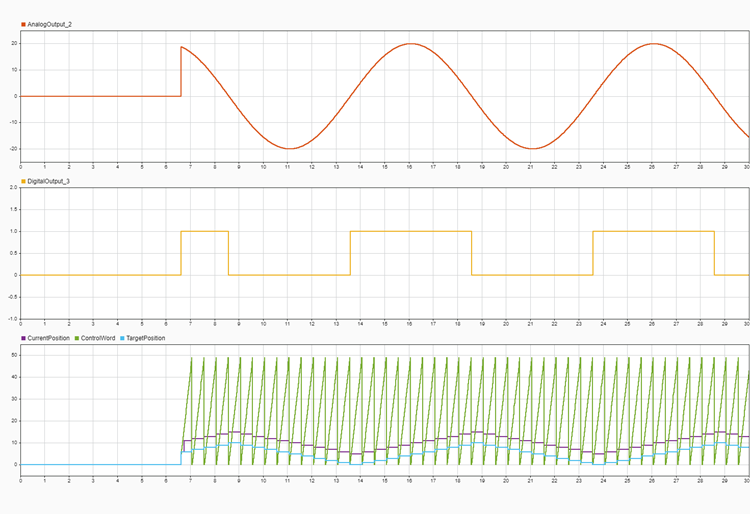

## Restore Target Machine Configuration

To restore the default configuration, you can simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5, and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_client)[EtherCAT Emulator documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_ecatsim)